# Coordinate systems

The representation of the eye and the scene in the model code makes use of two different coordinate frames. Rendered images of the eye have yet another coordinate frame. This script creates a labeled 3D plot that illustrates these frames and their relationship.

A right eye is illustrated.

% Get the default sceneGeometry
sceneGeometry = createSceneGeometry();

## Eye coordinate space

units of mm

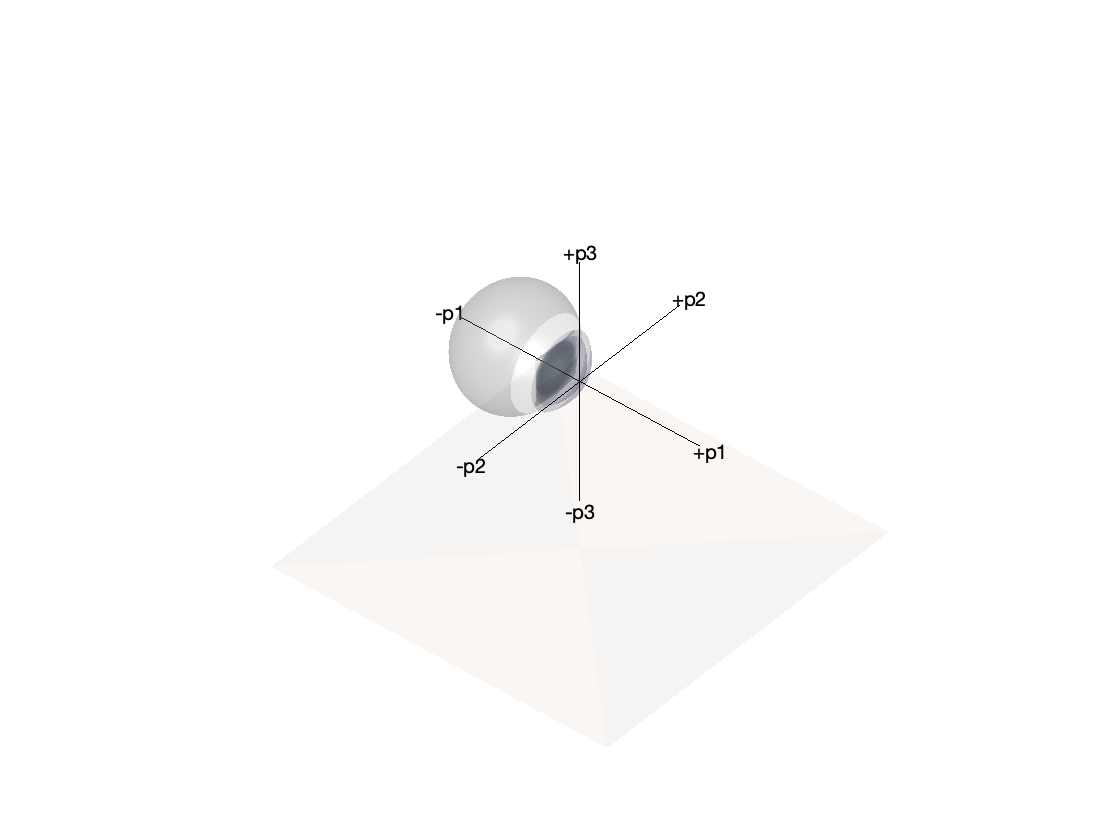

% Prepare a figure
figure('Name','Eye coordinates')

% Add the eye
plotOpticalSystem(sceneGeometry,'newFigure',false,'surfaceAlpha',0.4);

% Add axis lines for the eye coordinate system
plot3([-25 25],[0 0],[0 0],'-k')
plot3([0 0],[-25 25],[0 0],'-k')
plot3([0 0],[0 0],[-25 25],'-k')

% Add end-axis labels
text(-27,0,0,'-p1','HorizontalAlignment','center'); text(+27,0,0,'+p1','HorizontalAlignment','center');
text(0,-27,0,'-p2','HorizontalAlignment','center'); text(0,+27,0,'+p2','HorizontalAlignment','center');
text(0,0,-27,'-p3','HorizontalAlignment','center'); text(0,0,+27,'+p3','HorizontalAlignment','center');

% Indicate floor
f = fill3([-35 35 -35 35],[35 35 -35 -35],[-35 -35 -35 -35],[0.7 0.4 0.1],'LineStyle','none');
set(f,'facealpha',0.05)
f = fill3([-35 -35 35 35],[35 -35 35 -35],[-35 -35 -35 -35],[0.7 0.4 0.1],'LineStyle','none');
set(f,'facealpha',0.05)
axis off

## World coordinate space

units of mm

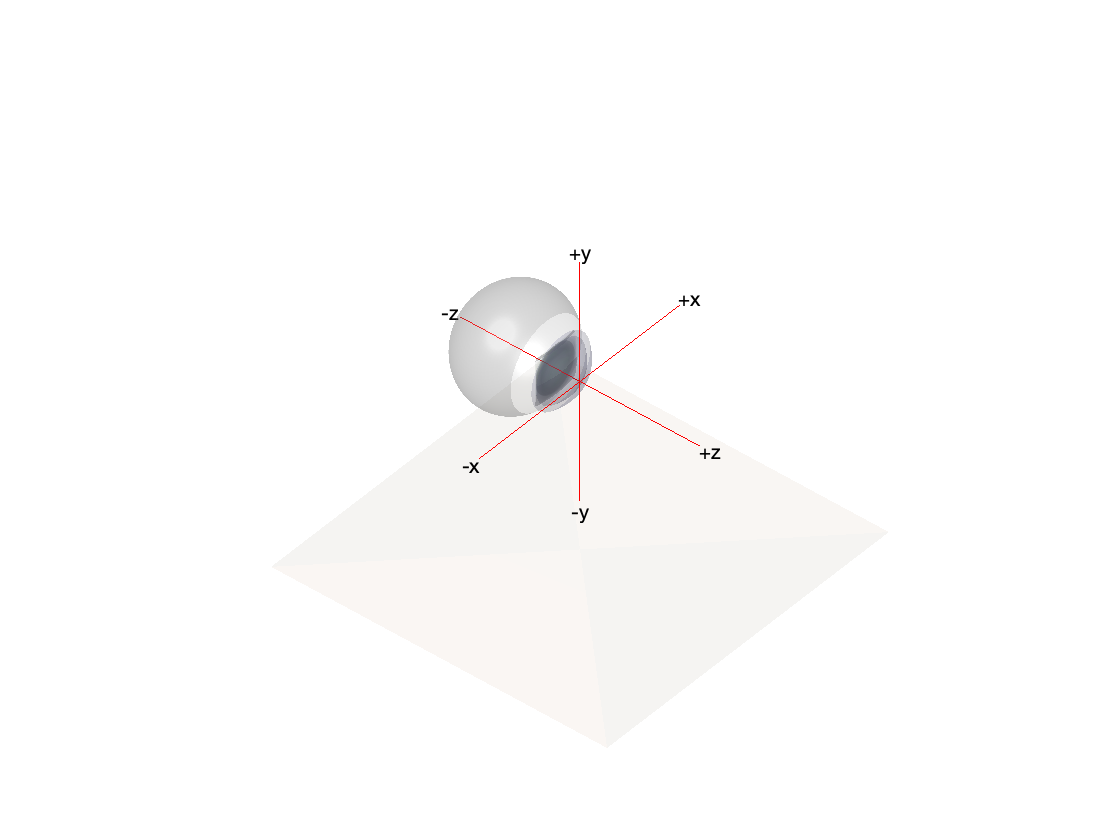

% Prepare a figure
figure('Name','World coordinates')

% Add the eye
plotOpticalSystem(sceneGeometry,'newFigure',false,'surfaceAlpha',0.4);

% Add axis lines for the eyeWorld space
plot3([-25 25],[0 0],[0 0],'-r')
plot3([0 0],[-25 25],[0 0],'-r')
plot3([0 0],[0 0],[-25 25],'-r')

% Add end-axis labels
text(-27,0,0,'-z','HorizontalAlignment','center'); text(+27,0,0,'+z','HorizontalAlignment','center');
text(0,-27,0,'-x','HorizontalAlignment','center'); text(0,+27,0,'+x','HorizontalAlignment','center');
text(0,0,-27,'-y','HorizontalAlignment','center'); text(0,0,+27,'+y','HorizontalAlignment','center');

% Indicate floor
f = fill3([-35 35 -35 35],[35 35 -35 -35],[-35 -35 -35 -35],[0.7 0.4 0.1],'LineStyle','none');
set(f,'facealpha',0.05)
f = fill3([-35 -35 35 35],[35 -35 35 -35],[-35 -35 -35 -35],[0.7 0.4 0.1],'LineStyle','none');
set(f,'facealpha',0.05)
axis off

## Image coordinate space

units of pixels

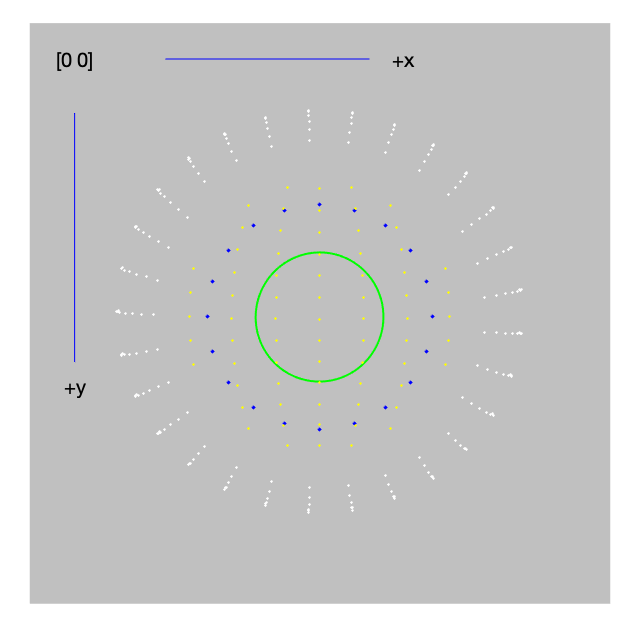

% Prepare a figure
figure('Name','Image coordinates')

% Add the eye
imageSizeX = sceneGeometry.cameraIntrinsic.sensorResolution(1);
imageSizeY = sceneGeometry.cameraIntrinsic.sensorResolution(2);
backgroundImage = zeros(imageSizeX,imageSizeX)+0.75;
imshow(backgroundImage,[], 'Border', 'tight');
hold on

% Translate the camera up a bit so that the rendered eye is drawn in the
% middle of the frame
sceneGeometry.cameraPosition.translation(2)=4;

% Render the eye
backgroundImage = zeros(imageSizeY,imageSizeX)+0.75;
eyePose = [0 0 0 3];
renderEyePose(eyePose, sceneGeometry,...
    'newFigure',false,...
    'modelEyeLabelNames', {'retina' 'irisPerimeter' 'pupilEllipse' 'cornea'},...
	'modelEyePlotColors', {'.w' 'ob' '-g' '.y'},...
	'modelEyeSymbolSizeScaler',0.5);

% Add some coordinate plots
hold on
text(50,40,'[0 0]','HorizontalAlignment','center');
text(400,40,'+x','HorizontalAlignment','left');
text(50,400,'+y','HorizontalAlignment','center');
plot([150 375],[40 40],'-b')
plot([50 50],[100 375],'-b')
ylim([-25 680.5]);